#  realizacion de un eco

## se realizara un eco intentando recrear los efectos naturales del fenomeno

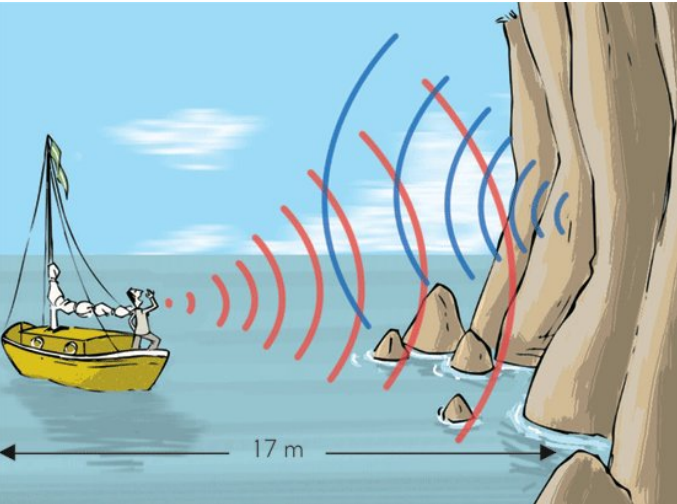

seteos del efecto 

 T = 0.1;   % Retraso en segundos (emula distancia al retorno de sonido, el la imagen, los 17m)
 G = 0.7;   % Amplitud del efecto (volumen de ese retorno, afectado por la forma de la pared)      
 

## Se toma el audio, y se lo recorta en relación a las muestras

para este caso, la frecuencia de muestreo (o sampling, de alli fs), por lo cual, en el ejemplo, fs indica que existen 44100 muestras por segundo, si quiero recurtar a medio segundo, basta con tomar 22050 muestras, y en general fs*Duracion nos abstrae y permite solo variar dicha variable para otros tiempos.

Accesoriamente, se toma un solo canal (el izquierdo) tomando solo la columna 1.

%% cargo el audio
[cancion, fs]=audioread('palmada.wav');
% tiempo en segundos del archivo de audio a procesar
DURACION = 1.184;
% me queda 
signal = cancion(1:fs*DURACION,1);        

## Busco el largo de la señal y genero el vector de tiempos

tam= length(signal);

t = 0:   (1/fs)  :  ( (tam-1)/fs );

% Transforma segundos de retardo a muestras
    M = floor(fs*T);
    
% Inicializa la salida, equivale, para el caso a hacer y=zeros(tam,1), solo busca setear el largo
    y = signal;
    
% Requiere memoria del largo del delay (en muestras)
    Delayline = zeros(M,1);

% Aplica eco a las muestras, mostrar ambos, guardando in o out
    tic; % inicio del cronometro
    for n=1:tam;
        y(n)=signal(n) - G*Delayline(M);    % le resta la muestra guardada mas vieja, la del indice M
        Delayline=[y(n); Delayline(1:M-1)]; % pongo en la posicion 1 la nueva muestra y descarto la M
    end;
    toc;% fin del cronometro

Elapsed time is 1.040521 seconds.


    a1=subplot(121),plot(t,signal);title('original');

a1 =   Axes (original) with properties:

             XLim: [0 1.5000]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


    
    a2=subplot(122),plot(t,y);title('con eco');

a2 =   Axes (con eco) with properties:

             XLim: [0 1.5000]
             YLim: [-1 1]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.5703 0.1100 0.3347 0.8150]
            Units: 'normalized'

  Show all properties


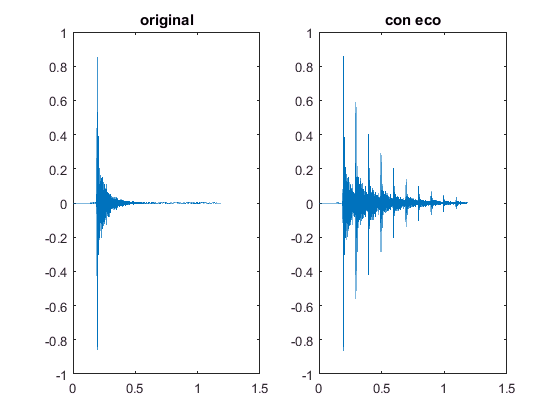

    linkaxes([a1 a2],'x'); %linkeo ejes x, para hacer zoom horizontal a ambas, probar con 'xy'

En un diagrama de bloques simplificado lo que hemos hecho es el siguiente:

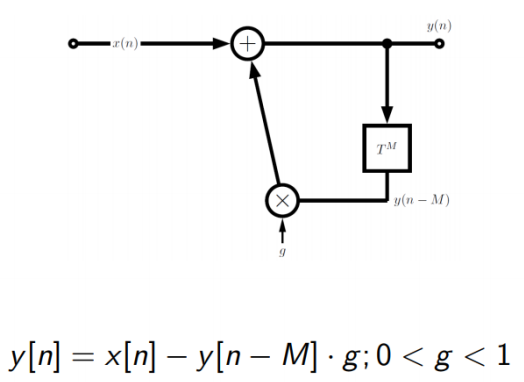

cuyos resultados en comparación acustica es:

sound(signal,fs);
sound(y,fs);